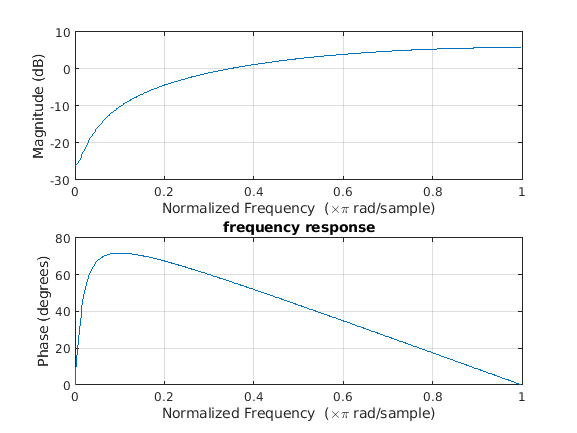

clear; clc; close all;
%frequency response of a filter with differencial equation  y[n]=x[n]-0.95*x[x-1]
h=[1 -0.95]; 
freqz(h); zoom on; grid on; 
title('frequency response')

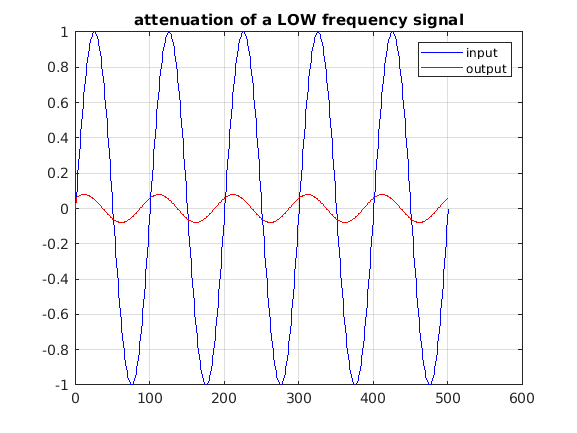

%attenuation of a LOW frequency signal
t=0:1:500;
f1=0.01;
x=sin(2*pi*f1*t);
y=filter(h,1,x);
figure; 
plot(x,'-b'); hold on;
plot(y, '-r'); zoom on; grid on;
legend('input', 'output');
title('attenuation of a LOW frequency signal')

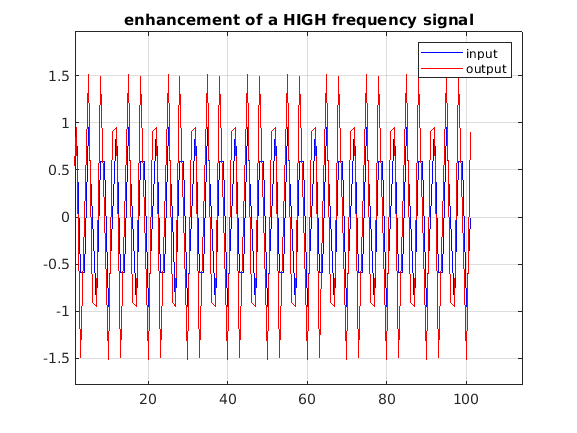

%enhancement of a HIGH frequency signal
t=0:1:100;
f1=0.3;
x=sin(2*pi*f1*t);
y=filter(h,1,x);
figure; 
plot(x,'-b'); hold on;
plot(y, '-r'); zoom on; grid on;
legend('input', 'output');
title('enhancement of a HIGH frequency signal');